## Test Env Module

env = Env();

[21-Dec-2021 20:30:48]: Creating Env object...
[21-Dec-2021 20:30:48]: Creating Planner object...
[21-Dec-2021 20:30:48]: Creating Reward object...
[21-Dec-2021 20:30:48]: Loding configuration info...


test function load scenario

[env, vehicleSet, vehiclesTrajectory] = env.load_scenario("Scenario/04.mat", 1);

[21-Dec-2021 20:30:48]: Loading Scenario Data from Scenario/04.mat...


test function load road

x = [-10, 0: 100: 500];
y = zeros(size(x));
waypoint = [x', y'];

env = env.load_road(waypoint, vehicleSet, vehiclesTrajectory);

[21-Dec-2021 20:30:48]: Loading road data...
[21-Dec-2021 20:30:48]: Creating Road object...
[21-Dec-2021 20:30:48]: Adding Vehicles object...


test function reset

% env = env.reset();

% env = env.reset('index', 9);

% env = env.reset('filename', 'Scenario/30.mat');

## Test Planner Module

% planner = Planner();
% 
% startState = [0, 10, 0];
% endState = [90, 20, 0];
% 
% resultS = planner.quintic_planning_s(startState, endState, 6, 0.04);
% 
% figure;
% hold on;
% plot(resultS.t, resultS.s);
% plot(resultS.t, resultS.s_dot);
% plot(resultS.t, resultS.s_ddot);
% hold off;
% 
% startStateD = [0, 0, 0];
% endStateD = [3.6, 0, 0];
% resultD = planner.quintic_planning_l(startStateD, endStateD, resultS);
% 
% figure;
% plot(resultD.t, resultD.l);
% hold on;
% plot(resultD.t, resultD.l_dot);
% plot(resultD.t, resultD.l_ddot);
% hold off;
% 
% startStateD = [1.8, 0, 0];
% endStateD = [5.4, 0, 0];
% resultD = planner.quartic_planning_l(startStateD, endStateD, resultS);
% 
% figure;
% plot(resultD.t, resultD.l);
% hold on;
% plot(resultD.t, resultD.l_dot);
% plot(resultD.t, resultD.l_ddot);
% hold off;
% 
% startState = [startState, startStateD];
% endState = [endState, endStateD];
% result1 = planner.get_trajectory(startState, endState, 6, 0.04, 1);
% planner.check_trajectory(result1.trajectory)
% result2 = planner.get_trajectory(startState, endState, 6, 0.04, 0);
% planner.check_trajectory(result2.trajectory)

test planner in env module

% startState = env.RoadInstance.get_vehicle_frenetstate(1)
% 
% endState = [env.Conf.MaxS, env.Conf.MaxSpeed, 0, 1.8, 0, 0]
% 
% T = 2 * (endState(1) - startState(1)) / (endState(2) + startState(2))
% 
% plannResult = env.PlannerInstance.get_trajectory(startState, endState, T, env.Conf.TimeResolution, 1);
% 
% env.PlannerInstance.check_trajectory(plannResult.trajectory);
% 
% globalTrajectory = env.RoadInstance.frenet_to_global_trajectory(plannResult.trajectory)

## Test Road Module

test function get current lane

% lane1 = road.get_current_lane([2.3, 1.8]);
% lane2 = road.get_current_lane([2.3, 5.4]);
% lane3 = road.get_current_lane([2.3, 9.0]);

test the transformer

% frenetTestAns = global2frenet(road.refPath, [10, 0, 0, 0, 0, 0]);
% GlobalTestAns = frenet2global(road.refPath, [20, 0, 0, 5.4, 0, 0]);

test function get surrounding car

% frontCar = {};
% behindCar = {};
% for i = 1:9
%     [frontCar{i}, behindCar{i}] = road.get_surrounding_car(i);
% end

test function car to state

% state = {};
% for i = 1: 9
%     state{i} = road.car_to_state(i, frontCar{1, i}, behindCar{1, i});
% end

test function check collision

% flag = {};
% for i = 1: 9
%     flag{i} = road.check_collision(i);      % need to get global state of car firstly
% end

test road in env module

% [env.RoadInstance, moveResult] = env.RoadInstance.move_along_trajectory(globalTrajectory, 0);

## Test Vehicle Module

test construction function

% vehicle1 = Vehicle([2.3, 1.8]); % default construction function
% vehicle2 = Vehicle([2.3, 5.4], 'longvelocity', 3.0, 'latvelocity', 0, 'length', 4.0, 'width', 2.0, 'yaw', pi/6); % change default parameters

## Test Vistor Module

% plot(road.Vistor.Scenario);

test vistor in env module

% env.RoadInstance = env.RoadInstance.add_vistor(waypoint);
% 
% % 这玩意儿在这个实施编辑器显示不出来
% env.RoadInstance.move_along_trajectory_vistor(globalTrajectory, 0);

## Test Reward Module

% reward = Reward();

test cal all reward function

% reward = reward.cal_all_reward(result1.trajectory);

## Test Logger Module

## Test the Reinforcement Learning

Initiate the info of observation

obsInfo = rlNumericSpec([14, 1]);
obsInfo.Name = "State";
obsInfo.LowerLimit = [-1, -1,...
                      -1, -inf,...
                      -1, -inf,...
                      -1, -inf,...
                      -201, -inf,...
                      -201, -inf,...
                      -201, -inf];
obsInfo.UpperLimit = [500, inf,...
                      201, inf,...
                      201, inf,...
                      201, inf,...
                      1, inf,...
                      1, inf,...
                      1, inf];

Initiate the info of action

actInfo = rlNumericSpec([7, 1]);
actInfo.Name = "Action";
actInfo.LowerLimit = [0.1, -50, -50, -10, -10, -10, 0.1];
actInfo.UpperLimit = [500, 50, 50, 10, 10, 10, 10];

Initiate the rl env object

resetHandle = @() MyResetFunc(env);
stepHandle = @(Action, LoggedSignals) MyStepFunc(Action, LoggedSignals);

Initiate the rl func

rlEnv = rlFunctionEnv(obsInfo, actInfo, stepHandle, resetHandle);

[21-Dec-2021 20:40:08]: Env object reseting...
[21-Dec-2021 20:40:08]: Adding Vehicles object...


action =   307.8947   11.5713   11.5713    2.3143    2.3143    2.3143    6.1956
  403.1033   30.6168   30.6168    6.1234    6.1234    6.1234    8.0811
   50.4435  -39.9293  -39.9293   -7.9859   -7.9859   -7.9859    1.0970
  205.6956   -8.8727   -8.8727   -1.7745   -1.7745   -1.7745    4.1716
  135.6945  -22.8757  -22.8757   -4.5751   -4.5751   -4.5751    2.7853
  322.1621   14.4253   14.4253    2.8851    2.8851    2.8851    6.4781
  343.4940   18.6925   18.6925    3.7385    3.7385    3.7385    6.9006


[21-Dec-2021 20:40:08]: Env object reseting...
[21-Dec-2021 20:40:08]: Adding Vehicles object...


Initiate the networkd

%   initiate the critic Net
criticNet = [
    featureInputLayer(obsInfo.Dimension(1), 'Normalization', 'none', 'Name', 'State'),...          
    fullyConnectedLayer(100, 'Name', 'criticNetFC1'),...
    reluLayer('Name', 'criticNetRelu1'),...
    fullyConnectedLayer(100, 'Name', 'criticNetFC2'),...
    reluLayer('Name', 'criticNetRelu2'),...
    fullyConnectedLayer(1, 'Name', 'criticNetFC3'),...
    reluLayer('Name', 'Value')];        

%   initiate the actor Net
actorNet = [
    featureInputLayer(obsInfo.Dimension(1), 'Normalization', 'none', 'Name', 'State'),...          
    fullyConnectedLayer(100, 'Name', 'actorNetFC1'),...
    reluLayer('Name', 'actorNetRelu1'),...
    fullyConnectedLayer(100, 'Name', 'actorNetFC2'),...
    reluLayer('Name', 'actorNetRelu2'),...
    fullyConnectedLayer(actInfo.Dimension(1) * 2, 'Name', 'actorNetFC3'),...
    reluLayer('Name', 'Actor')];  
% 
% comPath = [additionLayer(2,'Name', 'add'),...
%     fullyConnectedLayer(1, 'Name', 'ComPathFC1'),...
%     reluLayer('Name', 'QValue')];
% 
% net = addLayers(layerGraph(obsPath), actorPath);
% net = addLayers(net, comPath);
% 
% net = connectLayers(net,'ObsOut', 'add/in1');
% net = connectLayers(net,'ActOut', 'add/in2');
% 
% net
% 
% figure;
% plot(net);
% title('QNetwork');

critic opts

%    https://ww2.mathworks.cn/help/reinforcement-learning/ug/create-policy-and-value-function-representations.html
repOpts = rlRepresentationOptions('LearnRate', 0.001, 'GradientThreshold', 1, 'UseDevice', 'gpu');

critic = rlValueRepresentation(criticNet, obsInfo, 'Observation', {'State'}, repOpts);

actor opts

actor = rlStochasticActorRepresentation(actorNet, obsInfo, actInfo,...
    'Observation',{'State'},repOpts);

agentOpts = rlACAgentOptions(...
    'DiscountFactor', 0.99);

agent = rlACAgent(actor, critic, agentOpts);

rl train opts

maxepisodes = 1000;
trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', 100, ...
    'Verbose', true,...
    'Plots', 'training-progress',...
    'StopTrainingCriteria', 'EpisodeReward',...
    'StopTrainingValue', 500,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',100);

train agent

[21-Dec-2021 20:40:11]: Env object reseting...
[21-Dec-2021 20:40:11]: Adding Vehicles object...


action = 1×7 single 行向量
    5.5028   35.6456   37.7142   15.1913    3.9862   -7.8147   23.9175


Episode:   1/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    1 | Episode Q0:     0.00
[21-Dec-2021 20:40:12]: Env object reseting...
[21-Dec-2021 20:40:12]: Adding Vehicles object...


action = 1×7 single 行向量
   32.1542   70.4777    2.8203         0   37.1888    5.0858         0


Episode:   2/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    2 | Episode Q0:     0.00
[21-Dec-2021 20:40:13]: Env object reseting...
[21-Dec-2021 20:40:13]: Adding Vehicles object...


action = 1×7 single 行向量
   51.2759   66.1545   52.5798         0   -3.2558    7.8720   21.2569


Episode:   3/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    3 | Episode Q0:     0.00
[21-Dec-2021 20:40:13]: Env object reseting...
[21-Dec-2021 20:40:13]: Adding Vehicles object...


action = 1×7 single 行向量
   43.1674   63.0294   22.2090         0         0   28.4476  -13.5470


Episode:   4/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    4 | Episode Q0:     0.00
[21-Dec-2021 20:40:14]: Env object reseting...
[21-Dec-2021 20:40:14]: Adding Vehicles object...


action = 1×7 single 行向量
   10.3051   39.0654   33.5569   17.2967         0    2.1476    6.2056


Episode:   5/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    5 | Episode Q0:     0.00
[21-Dec-2021 20:40:14]: Env object reseting...
[21-Dec-2021 20:40:14]: Adding Vehicles object...


action = 1×7 single 行向量
   39.3792   46.6715         0   12.2938         0   12.8223         0


Episode:   6/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    6 | Episode Q0:     0.00
[21-Dec-2021 20:40:14]: Env object reseting...
[21-Dec-2021 20:40:14]: Adding Vehicles object...


action = 1×7 single 行向量
    8.1464   11.5251    4.6870   10.7845         0         0   -2.5220


Episode:   7/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    7 | Episode Q0:     0.00
[21-Dec-2021 20:40:14]: Env object reseting...
[21-Dec-2021 20:40:14]: Adding Vehicles object...


action = 1×7 single 行向量
   43.3056   46.7317   24.6352    9.8666   -4.2500   -9.1425   -0.0377


Episode:   8/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    8 | Episode Q0:     0.00
[21-Dec-2021 20:40:14]: Env object reseting...
[21-Dec-2021 20:40:14]: Adding Vehicles object...


action = 1×7 single 行向量
    3.6880   56.9586   32.1237    8.4416   -3.6634         0  -11.1031


Episode:   9/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:    9 | Episode Q0:     0.00
[21-Dec-2021 20:40:15]: Env object reseting...
[21-Dec-2021 20:40:15]: Adding Vehicles object...


action = 1×7 single 行向量
    6.9836    9.5532    6.5044    9.4817         0         0    9.0126


Episode:  10/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   10 | Episode Q0:     0.00
[21-Dec-2021 20:40:15]: Env object reseting...
[21-Dec-2021 20:40:15]: Adding Vehicles object...


action = 1×7 single 行向量
   47.5668   47.7372   31.3188    9.5226    0.5659   -5.9076  -49.3382


Episode:  11/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   11 | Episode Q0:     0.00
[21-Dec-2021 20:40:15]: Env object reseting...
[21-Dec-2021 20:40:15]: Adding Vehicles object...


action = 1×7 single 行向量
   52.3116   49.3318         0    5.1557         0         0         0


Episode:  12/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   12 | Episode Q0:     0.00
[21-Dec-2021 20:40:15]: Env object reseting...
[21-Dec-2021 20:40:15]: Adding Vehicles object...


action = 1×7 single 行向量
   50.5073   49.1693         0   12.1024         0         0         0


Episode:  13/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   13 | Episode Q0:     0.00
[21-Dec-2021 20:40:15]: Env object reseting...
[21-Dec-2021 20:40:15]: Adding Vehicles object...


action = 1×7 single 行向量
   10.8947   43.2174   40.0695   19.7107   15.5525    4.5805 -109.5924


Episode:  14/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   14 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
   65.8043   47.1121   25.5238   29.0148         0         0  -10.7018


Episode:  15/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   15 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
   20.2648   48.4480   35.2636         0         0         0   -0.2188


Episode:  16/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   16 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
   69.5292   65.4942   33.0113         0         0   -5.9086  -10.9644


Episode:  17/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   17 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
   24.0277   47.0291   15.4152    1.0175         0         0   11.7233


Episode:  18/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   18 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
   16.8933   43.9888         0    7.3128         0   -2.9756         0


Episode:  19/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   19 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
   65.7664   54.3199   14.7309         0  -11.0428  -10.5435  -62.6824


Episode:  20/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   20 | Episode Q0:     0.00
[21-Dec-2021 20:40:16]: Env object reseting...
[21-Dec-2021 20:40:16]: Adding Vehicles object...


action = 1×7 single 行向量
    9.6801   10.9149   12.8859    8.3591         0         0  -14.5241


Episode:  21/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   21 | Episode Q0:     0.00
[21-Dec-2021 20:40:17]: Env object reseting...
[21-Dec-2021 20:40:17]: Adding Vehicles object...


action = 1×7 single 行向量
   66.8799   35.4040   28.3852   16.7828         0    2.4531   -0.5884


Episode:  22/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   22 | Episode Q0:     0.00
[21-Dec-2021 20:40:17]: Env object reseting...
[21-Dec-2021 20:40:17]: Adding Vehicles object...


action = 1×7 single 行向量
   34.5269   51.4881    5.4033    6.0240  -18.2368  -95.5488   -3.5237


Episode:  23/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   23 | Episode Q0:     0.00
[21-Dec-2021 20:40:18]: Env object reseting...
[21-Dec-2021 20:40:18]: Adding Vehicles object...


action = 1×7 single 行向量
   20.8781   43.1363         0    7.4711         0    2.8276         0


Episode:  24/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   24 | Episode Q0:     0.00
[21-Dec-2021 20:40:18]: Env object reseting...
[21-Dec-2021 20:40:18]: Adding Vehicles object...


action = 1×7 single 行向量
   40.0196   63.7293   31.1030         0         0    5.3248   15.2019


Episode:  25/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   25 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   80.3787   64.0648   27.2971         0         0  -14.0239   10.2285


Episode:  26/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   26 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   49.9832   92.4011   18.5452         0   -0.2890  -67.5005  -37.4604


Episode:  27/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   27 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   13.8046   50.3174   35.1050   -2.6218         0         0    4.1617


Episode:  28/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   28 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   48.6572   41.2644   13.0653   11.4823   -2.7893  -11.5590  -69.0847


Episode:  29/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   29 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   29.7497   35.6840   10.6722    8.1491    2.6749    2.4430   16.4632


Episode:  30/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   30 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   -7.1261   65.7022  -15.2091    5.4220   -8.8294         0  -29.2412


Episode:  31/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   31 | Episode Q0:     0.00
[21-Dec-2021 20:40:19]: Env object reseting...
[21-Dec-2021 20:40:19]: Adding Vehicles object...


action = 1×7 single 行向量
   23.6785   33.1988   37.1566   10.5765         0         0  -30.0260


Episode:  32/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   32 | Episode Q0:     0.00
[21-Dec-2021 20:40:20]: Env object reseting...
[21-Dec-2021 20:40:20]: Adding Vehicles object...


action = 1×7 single 行向量
   -9.0526   72.5319   10.5115    8.0422         0   12.8693         0


Episode:  33/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   33 | Episode Q0:     0.00
[21-Dec-2021 20:40:20]: Env object reseting...
[21-Dec-2021 20:40:20]: Adding Vehicles object...


action = 1×7 single 行向量
   58.4754   52.8858    0.7512   31.4162    9.0483         0         0


Episode:  34/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   34 | Episode Q0:     0.00
[21-Dec-2021 20:40:20]: Env object reseting...
[21-Dec-2021 20:40:20]: Adding Vehicles object...


action = 1×7 single 行向量
    3.8666   43.7063         0    8.6228         0    6.0711         0


Episode:  35/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   35 | Episode Q0:     0.00
[21-Dec-2021 20:40:20]: Env object reseting...
[21-Dec-2021 20:40:20]: Adding Vehicles object...


action = 1×7 single 行向量
   89.0834   64.1355   20.5540   -0.9714    3.1724   -3.2300 -125.2381


Episode:  36/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   36 | Episode Q0:     0.00
[21-Dec-2021 20:40:20]: Env object reseting...
[21-Dec-2021 20:40:20]: Adding Vehicles object...


action = 1×7 single 行向量
   35.0583   73.5842   32.6782         0         0   -9.6814         0


Episode:  37/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   37 | Episode Q0:     0.00
[21-Dec-2021 20:40:21]: Env object reseting...
[21-Dec-2021 20:40:21]: Adding Vehicles object...


action = 1×7 single 行向量
  108.8621   65.0162   22.8825   -2.4779   57.5367  -63.2002  -23.2065


Episode:  38/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   38 | Episode Q0:     0.00
[21-Dec-2021 20:40:21]: Env object reseting...
[21-Dec-2021 20:40:21]: Adding Vehicles object...


action = 1×7 single 行向量
   44.7543   45.3636   21.7784   -6.2002    0.3238    6.8628  -21.2580


Episode:  39/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   39 | Episode Q0:     0.00
[21-Dec-2021 20:40:21]: Env object reseting...
[21-Dec-2021 20:40:21]: Adding Vehicles object...


action = 1×7 single 行向量
  103.3833   65.5565   23.9895    8.1892  -43.5877   29.1649   30.6622


Episode:  40/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   40 | Episode Q0:     0.00
[21-Dec-2021 20:40:21]: Env object reseting...
[21-Dec-2021 20:40:21]: Adding Vehicles object...


action = 1×7 single 行向量
   41.5308   47.4678   33.8341   41.2852    0.5308   13.6776  102.2555


Episode:  41/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   41 | Episode Q0:     0.00
[21-Dec-2021 20:40:21]: Env object reseting...
[21-Dec-2021 20:40:21]: Adding Vehicles object...


action = 1×7 single 行向量
   16.9600   42.4914         0  103.2298         0    3.8226    1.4181


Episode:  42/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   42 | Episode Q0:     0.00
[21-Dec-2021 20:40:22]: Env object reseting...
[21-Dec-2021 20:40:22]: Adding Vehicles object...


action = 1×7 single 行向量
  122.7386   52.7113    5.1516   71.5326   -0.7701    7.3758   -0.1553


Episode:  43/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   43 | Episode Q0:     0.00
[21-Dec-2021 20:40:22]: Env object reseting...
[21-Dec-2021 20:40:22]: Adding Vehicles object...


action = 1×7 single 行向量
   77.9202   52.3950    6.2660    6.0500   -1.9638  -13.6204         0


Episode:  44/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   44 | Episode Q0:     0.00
[21-Dec-2021 20:40:22]: Env object reseting...
[21-Dec-2021 20:40:22]: Adding Vehicles object...


action = 1×7 single 行向量
  102.4108   65.5814   48.2287   36.1254   -7.7011         0    6.0290


Episode:  45/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   45 | Episode Q0:     0.00
[21-Dec-2021 20:40:22]: Env object reseting...
[21-Dec-2021 20:40:22]: Adding Vehicles object...


action = 1×7 single 行向量
   77.1916   51.4431    9.6313   -7.5619   -5.8666   41.2281    3.7843


Episode:  46/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   46 | Episode Q0:     0.00
[21-Dec-2021 20:40:23]: Env object reseting...
[21-Dec-2021 20:40:23]: Adding Vehicles object...


action = 1×7 single 行向量
   41.4790   43.6418   15.5172   -1.2788   82.7425    5.2352  -66.0547


Episode:  47/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   47 | Episode Q0:     0.00
[21-Dec-2021 20:40:23]: Env object reseting...
[21-Dec-2021 20:40:23]: Adding Vehicles object...


action = 1×7 single 行向量
  177.6167   52.9538   45.4189   77.1854   76.7254  -64.7230  -35.1717


Episode:  48/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   48 | Episode Q0:     0.00
[21-Dec-2021 20:40:23]: Env object reseting...
[21-Dec-2021 20:40:23]: Adding Vehicles object...


action = 1×7 single 行向量
  -18.3568   44.3162   -1.2399  -57.5725         0    0.2091    3.6502


Episode:  49/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   49 | Episode Q0:     0.00
[21-Dec-2021 20:40:23]: Env object reseting...
[21-Dec-2021 20:40:23]: Adding Vehicles object...


action = 1×7
   66.4398   49.8482   50.1003   16.0379   27.8853   50.7459  -40.1682


Episode:  50/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   50 | Episode Q0:     0.00
[21-Dec-2021 20:40:23]: Env object reseting...
[21-Dec-2021 20:40:23]: Adding Vehicles object...


action = 1×7
   28.8563   62.1441   -0.7202  148.8648 -107.3323   81.4957    6.4167


Episode:  51/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   51 | Episode Q0:     0.00
[21-Dec-2021 20:40:23]: Env object reseting...
[21-Dec-2021 20:40:23]: Adding Vehicles object...


action = 1×7
    4.8287   38.8253    0.0436  -65.0533   -0.3400   44.2487    3.5004


Episode:  52/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   52 | Episode Q0:     0.00
[21-Dec-2021 20:40:24]: Env object reseting...
[21-Dec-2021 20:40:24]: Adding Vehicles object...


action = 1×7
   13.1655   10.2323   24.0536   16.5210  -10.3865         0  -34.7771


Episode:  53/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   53 | Episode Q0:     0.00
[21-Dec-2021 20:40:24]: Env object reseting...
[21-Dec-2021 20:40:24]: Adding Vehicles object...


action = 1×7
   35.4146   50.6657    9.9617   21.3613   55.4505  -75.0906  110.9452


Episode:  54/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   54 | Episode Q0:     0.00
[21-Dec-2021 20:40:24]: Env object reseting...
[21-Dec-2021 20:40:24]: Adding Vehicles object...


action = 1×7
  -14.1650   76.5951   29.2597  -57.5116    6.6123   97.9968  -18.8451


Episode:  55/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   55 | Episode Q0:     0.00
[21-Dec-2021 20:40:24]: Env object reseting...
[21-Dec-2021 20:40:24]: Adding Vehicles object...


action = 1×7
   48.5473   42.9726   41.8847   47.9271   -0.4860   60.0500    8.8213


Episode:  56/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   56 | Episode Q0:     0.00
[21-Dec-2021 20:40:24]: Env object reseting...
[21-Dec-2021 20:40:24]: Adding Vehicles object...


action = 1×7
   -6.1440   14.4868    6.4242    1.3714   -8.2496   -2.0059   38.0484


Episode:  57/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   57 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
  109.8096   76.4192   17.4144   22.9550  -10.8161 -136.8656   17.9817


Episode:  58/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   58 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
   35.6214   10.6836    7.0018   48.3130    0.5701    5.5792  -12.8057


Episode:  59/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   59 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
  100.4043   81.2917   69.0520  -37.7524    7.4671   75.9068  -53.3607


Episode:  60/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   60 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
   30.2176   10.2798   38.0984  -15.5775   10.0239   -1.0152  -44.4928


Episode:  61/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   61 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
   39.3458   36.1120    0.5293   25.9977   35.8065    3.6325  -10.6860


Episode:  62/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   62 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
   81.3310   63.0382   19.0596   -3.2620   84.5589   60.4439  -25.9322


Episode:  63/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   63 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
   83.1398   48.4989   20.7253   28.4176  -56.8587  -28.5230   48.5931


Episode:  64/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   64 | Episode Q0:     0.00
[21-Dec-2021 20:40:25]: Env object reseting...
[21-Dec-2021 20:40:25]: Adding Vehicles object...


action = 1×7
   -5.7331   74.5742   10.7581   49.2878   29.9669    6.3141  -80.2077


Episode:  65/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   65 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
   95.4906   72.9998   33.2231   15.3666  -85.5390   33.1744    4.3661


Episode:  66/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   66 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
   35.0078   36.9048   21.3519   50.4235   65.8097    4.0590   22.5241


Episode:  67/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   67 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
   60.1175   53.3632  -13.1774   48.0468   30.4436 -157.0494  -37.6363


Episode:  68/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   68 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
   28.6052   50.8691   39.8485  -35.9026  -87.1695   19.5924  -21.3866


Episode:  69/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   69 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
   96.2551   64.6794   49.7591   59.5518 -154.8221   67.8763    8.2173


Episode:  70/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   70 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
  142.4734   22.1510  -34.8770   45.3530   11.2668  -24.2286  -78.1337


Episode:  71/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   71 | Episode Q0:     0.00
[21-Dec-2021 20:40:26]: Env object reseting...
[21-Dec-2021 20:40:26]: Adding Vehicles object...


action = 1×7
   96.4471   69.6165   74.9579  -25.4028   79.9993         0   50.9666


Episode:  72/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   72 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
    7.4201  122.1676  -83.0522   50.2466  169.6824 -183.6007   45.9187


Episode:  73/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   73 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
   18.8923   23.0138   -9.9777   14.6512   14.9999   19.4227  -41.4807


Episode:  74/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   74 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
   78.0290   65.4981   38.9175 -175.0222   -8.8175  -40.2055   63.8944


Episode:  75/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   75 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
  109.6504   59.0933  -10.0734  -14.1246   71.4153   15.3972  -30.7340


Episode:  76/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   76 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
  -32.0910   42.4301    7.5272   -7.1863   -5.5820  -16.9638  -34.1740


Episode:  77/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   77 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
  113.8108   76.3556  -87.7782   98.1629   52.3966   -0.9469   -1.8020


Episode:  78/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   78 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
   46.8152   11.6510   -7.1130   67.5150    3.8141         0  -24.6984


Episode:  79/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   79 | Episode Q0:     0.00
[21-Dec-2021 20:40:27]: Env object reseting...
[21-Dec-2021 20:40:27]: Adding Vehicles object...


action = 1×7
   36.2842   83.2863  122.4578   46.4774 -132.1235  -60.5293   54.9174


Episode:  80/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   80 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   28.2977   59.1712  145.3343  -19.0445   21.0521  -10.7863   96.9891


Episode:  81/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   81 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
    8.2860   56.5097  -32.8898  -63.4920  119.4250   14.5890   -3.5845


Episode:  82/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   82 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   39.6258   60.8109  -17.2201   37.1986   88.2282  -31.7846   -1.0750


Episode:  83/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   83 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   42.3048   39.2863   33.0165   29.0221  -27.5915    1.3395  -52.4301


Episode:  84/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   84 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   78.1814    0.6704  -63.1234  123.0022  -52.9332   12.2449  -38.6495


Episode:  85/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   85 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   86.4521   51.8100  -45.6288   70.9381 -133.6574  -32.2609   61.0962


Episode:  86/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   86 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
  100.4288   27.1774  149.2591  -36.0693   51.8199    7.1206   29.3108


Episode:  87/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   87 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   40.3970   35.3130   -1.8696   50.2621   46.9388  -64.4566    5.9146


Episode:  88/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   88 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
  -91.8724   59.0284  -32.7220 -142.1508  -22.6950   -0.0561   13.4831


Episode:  89/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   89 | Episode Q0:     0.00
[21-Dec-2021 20:40:28]: Env object reseting...
[21-Dec-2021 20:40:28]: Adding Vehicles object...


action = 1×7
   80.8915   33.7425   11.2942  230.6031   92.3940   12.9651  125.2901


Episode:  90/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   90 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
   11.4657   27.7627   28.4791  -54.6586   28.1731    2.3333  -42.0940


Episode:  91/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   91 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
   80.1895   26.1577  157.5837  145.6219   19.5436   42.8360  -13.8339


Episode:  92/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   92 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
  158.2938   35.8386  -27.9612  -81.5839  -40.1322 -121.3264   75.5192


Episode:  93/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   93 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
   63.5413   12.2978   20.3590   14.5070   35.6328    2.1639   62.0892


Episode:  94/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   94 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
    7.9769   66.0358 -150.1668  -37.3568  -15.5699   22.2701 -112.2276


Episode:  95/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   95 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
   51.4981   37.7394  -39.2754  -29.2593   40.1521  -20.0955  101.8299


Episode:  96/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   96 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
  157.3242   87.7892   13.3983  -13.5320  -13.1893  -82.2965  105.6726


Episode:  97/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   97 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
   21.6108   11.1725   13.6444    6.9612   -7.4329    9.6057   15.3123


Episode:  98/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   98 | Episode Q0:     0.00
[21-Dec-2021 20:40:29]: Env object reseting...
[21-Dec-2021 20:40:29]: Adding Vehicles object...


action = 1×7
   42.3690   -0.0800  -15.4975  -73.3648  -10.6250   -0.4269   58.9620


Episode:  99/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:   99 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
   23.7690  109.0660   56.2902  -34.8371  -75.2523   12.5241   -6.4286


Episode: 100/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  100 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
  -37.5828   75.4268  -59.7672  -50.7991  108.5154  -93.7718 -146.4952


Episode: 101/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  101 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
  184.6933   40.4851  -26.0729   79.1660  -54.7903  228.9672  -72.3818


Episode: 102/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  102 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
   79.4479  101.2424    1.6730   62.2491   13.4853   71.7552   -7.1517


Episode: 103/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  103 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
   58.7719   66.1657 -154.1203   -6.5442  140.5832  -51.7401   22.4644


Episode: 104/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  104 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
   13.5694    6.2517   -7.5380    1.4824  -10.5315    2.9655  -30.7129


Episode: 105/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  105 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
  345.6580   91.7586   26.8256 -158.1866   56.7483  105.1693   13.2513


Episode: 106/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  106 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
   -7.8662   26.0949   19.3001  142.3604   43.9675 -141.6159   -7.5434


Episode: 107/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  107 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
   10.5402   85.3709  -66.6776  102.3677  184.8814    8.8947  -60.5450


Episode: 108/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  108 | Episode Q0:     0.00
[21-Dec-2021 20:40:30]: Env object reseting...
[21-Dec-2021 20:40:30]: Adding Vehicles object...


action = 1×7
  -50.1414   20.0493   14.2637  -27.1682   11.5255    0.0133   11.1656


Episode: 109/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  109 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
   11.1882   11.3172   30.1188   -9.6041   -4.1085   12.7193   33.0204


Episode: 110/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  110 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
  109.8744  122.0784   -2.9943   34.0712  -22.1205 -130.4865  131.4577


Episode: 111/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  111 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
   59.6867   49.8195 -138.8250   10.7060  -42.0513   39.5287  -55.9168


Episode: 112/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  112 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
   24.2651  280.2113 -103.0850  141.7789 -292.4672  -44.8080  -66.3844


Episode: 113/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  113 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
  195.6977  132.8923  106.8577   90.8562 -122.9366   18.9260  -81.3984


Episode: 114/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  114 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
  214.6098  125.9540   -8.4649  235.5663    2.4228   66.1037   42.6403


Episode: 115/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  115 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
  -68.9889   98.6994  -66.6436  -17.4251  -18.3281  -74.3153  123.6183


Episode: 116/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  116 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
   55.7859   23.0876    4.2396   -1.1244  -16.8567  -50.8852   26.5405


Episode: 117/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  117 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
  134.1669  131.5897   78.9078  241.1952  -24.7561   24.1109  -28.5973


Episode: 118/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  118 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
  120.2017  132.0690   68.5933   33.7271   28.0182 -178.6589   22.7529


Episode: 119/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  119 | Episode Q0:     0.00
[21-Dec-2021 20:40:31]: Env object reseting...
[21-Dec-2021 20:40:31]: Adding Vehicles object...


action = 1×7
   99.4566   50.3094  114.0131   50.4743  -49.6983 -169.9300  -41.8609


Episode: 120/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  120 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
   20.8193   22.1090  -33.8257  -27.5126   17.4113   -8.0731  -50.1218


Episode: 121/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  121 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
   78.8251  118.8137  119.5916  207.3306  101.5016 -115.3184 -108.7662


Episode: 122/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  122 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
 -123.3416  129.3144 -257.3754  224.3403  -20.8293 -138.7444  136.6262


Episode: 123/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  123 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
  126.3065  -38.3016   70.9183   16.2255  -90.5471 -128.5623   48.1096


Episode: 124/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  124 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
   20.9144  147.7215    9.6851 -236.5983   26.5600 -139.0591  213.7962


Episode: 125/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  125 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
  147.8494   20.1881  -38.1825  107.4354   -4.2575   16.7290   61.6145


Episode: 126/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  126 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
   34.8345   82.8353  -96.4688  150.2601  -87.1444  -26.6664   13.2772


Episode: 127/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  127 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
   53.1961   15.2482   29.3846  -32.8174  -41.2352   -1.5025   24.3233


Episode: 128/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  128 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
  -11.7211   46.6897   43.7806   22.4261   18.0464   91.0824  -17.6709


Episode: 129/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  129 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
  153.6318   82.4793  151.8867  -26.4875    3.0868   93.9188  -13.2197


Episode: 130/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  130 | Episode Q0:     0.00
[21-Dec-2021 20:40:32]: Env object reseting...
[21-Dec-2021 20:40:32]: Adding Vehicles object...


action = 1×7
   91.5871  124.7447 -286.4754  -61.7834  -16.1142   14.2775  -29.0783


Episode: 131/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  131 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
  333.2910  243.9514  -26.7144  173.7826   73.3928   67.6662 -224.5051


Episode: 132/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  132 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
   53.8865   45.2601   16.8625  217.9691  267.7700  191.3562 -114.0105


Episode: 133/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  133 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
   55.3214 -243.1137  -57.1852  159.4630  -50.2376  -41.9383  -13.2480


Episode: 134/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  134 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
   22.0042   59.9688  -28.8322  -75.6125   29.8046   43.6766  -54.9225


Episode: 135/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  135 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
   35.4646   62.8427   52.4112  -11.1786    3.8870   41.8657   76.7293


Episode: 136/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  136 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
  573.4382  126.1056 -227.5127  -17.0285  388.0153  113.6897   -3.9595


Episode: 137/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  137 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
  140.0133  299.2101 -300.5963  -46.3033    5.9862   94.4866  -76.9766


Episode: 138/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  138 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
   46.0790  149.6538 -116.4684  -37.9529   30.4895    9.1808    4.5205


Episode: 139/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  139 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
 -195.9080  199.2336  -29.9870 -116.9941  389.5532 -146.2622   43.1893


Episode: 140/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  140 | Episode Q0:     0.00
[21-Dec-2021 20:40:33]: Env object reseting...
[21-Dec-2021 20:40:33]: Adding Vehicles object...


action = 1×7
   29.1461   33.0057  -15.7568  -46.1906  423.9849   98.2618  129.6271


Episode: 141/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  141 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
 -113.7187  103.3672   -8.7314  214.7724   27.1369   15.6050   49.6157


Episode: 142/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  142 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
 -128.2545  114.5733   -6.2946 -169.1735  -79.8521   59.4806   28.6886


Episode: 143/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  143 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
   51.3556   94.2820  457.2619  -66.8749   10.0973   28.8916  142.8025


Episode: 144/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  144 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
  419.5071   20.1571  -78.3602  -30.7992  197.4081  -73.9986  -16.0566


Episode: 145/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  145 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
  -46.1422  110.1321   -7.5906  -40.5878   65.1264   28.7916   12.3475


Episode: 146/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  146 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
  -22.7441  386.9323 -112.9444  -95.3737  345.8401    9.1935  -51.6114


Episode: 147/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  147 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
   67.3814  149.9130   56.2743  -49.1196  -84.1651  -87.4630    5.6603


Episode: 148/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  148 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
   21.8762   13.2268   28.1738   18.4382   50.3490   -6.2707   -7.6781


Episode: 149/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  149 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
  -17.2225   66.3223  -41.8991   47.4446   -4.2413   -4.0261   27.8498


Episode: 150/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  150 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
   97.3132   70.6967  197.0727  -46.5597   64.5733  -18.6666  120.0143


Episode: 151/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  151 | Episode Q0:     0.00
[21-Dec-2021 20:40:34]: Env object reseting...
[21-Dec-2021 20:40:34]: Adding Vehicles object...


action = 1×7
  112.6772  -62.6345   12.8501 -109.0549 -111.2855   71.7296  -45.8095


Episode: 152/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  152 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  -42.0197  236.9889  207.3644 -159.2333  130.4393 -158.8182 -324.0071


Episode: 153/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  153 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
   27.3489   23.3872  -31.8900 -117.4496  163.9072  -92.7274 -136.8097


Episode: 154/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  154 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  113.7773  -12.7449   60.1932  138.7077 -163.2164   22.3012   95.3268


Episode: 155/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  155 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  154.5462  111.5551 -101.6567   52.4395  101.2056  -94.2267  -40.7904


Episode: 156/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  156 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
   90.3239   22.3916 -125.2504   50.1857   30.7359   17.6844   40.3529


Episode: 157/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  157 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  163.2897    7.9454  157.8900   21.9053  -80.3907   45.7731   58.4584


Episode: 158/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  158 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
   51.4383   18.7729   70.2037  -60.6543  169.8895 -124.8041  -35.6578


Episode: 159/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  159 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  319.8948  159.8228  126.0980  -56.6549  -28.0662  -39.4888  -15.0435


Episode: 160/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  160 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  178.8700   -3.2447  203.5719   16.3440   38.2277  -38.7267  -25.7545


Episode: 161/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  161 | Episode Q0:     0.00
[21-Dec-2021 20:40:35]: Env object reseting...
[21-Dec-2021 20:40:35]: Adding Vehicles object...


action = 1×7
  121.3610  -87.9687  -44.7039   44.2138  -27.4969   19.5808  -61.4152


Episode: 162/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  162 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
  161.9922   95.4503 -208.5694  -41.2607   15.9896  -64.2467  -69.1391


Episode: 163/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  163 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
 -243.0893  143.9373  216.3213  160.8696   -1.2426  -69.7312    8.1369


Episode: 164/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  164 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
  -44.6925  156.4462    1.0314 -100.9278 -311.4981  -14.9068  -93.7040


Episode: 165/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  165 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
  213.7269   24.7017  -86.9821   29.5747   37.7483  -47.7578   -3.1223


Episode: 166/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  166 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
  198.9836   65.6500   98.2838  -23.0430   15.3352  178.0182    4.0310


Episode: 167/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  167 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
   25.7848   99.0668  166.4062   15.4431  -20.3651   31.9127 -144.8225


Episode: 168/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  168 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
  133.5877  194.1846 -229.4905  339.3461   43.4978 -158.3898  132.8643


Episode: 169/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  169 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
   32.5467   46.7318   23.7587   -1.7465   41.2232 -109.0235   -8.0839


Episode: 170/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  170 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
   76.6165   38.0823 -103.6266  -87.1932  -61.6984   65.4034   41.1933


Episode: 171/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  171 | Episode Q0:     0.00
[21-Dec-2021 20:40:36]: Env object reseting...
[21-Dec-2021 20:40:36]: Adding Vehicles object...


action = 1×7
   86.6510  177.8666  -43.2070  -43.6450  -47.7620 -103.4837  119.4236


Episode: 172/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  172 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
  -19.2550  167.6327  211.7760   43.5505 -113.9598   27.2682   20.3931


Episode: 173/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  173 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
  -55.7043   88.4268  -32.7406   -8.4852   17.4743   25.2646   -3.6739


Episode: 174/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  174 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
   33.9392  258.8072  220.1885   49.0710   49.1150  -41.6477   51.8829


Episode: 175/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  175 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
   -2.1926  -30.2284  -31.7967  -18.3538    5.5931    8.4705   -0.2201


Episode: 176/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  176 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
    5.3583  182.5015    2.2855  116.1526  -44.6467   48.2385  -98.8985


Episode: 177/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  177 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
   51.1161  167.6219 -128.2088   12.6304 -208.0028 -210.7482  -29.4954


Episode: 178/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  178 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
  101.6201   80.5867   24.4980  172.7607  164.8033   78.1115  -25.8587


Episode: 179/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  179 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
   47.8157  218.5310  322.2898   38.2885   48.3936  -75.1282   48.3343


Episode: 180/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  180 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
   19.4092  157.1368 -171.5525  101.3216  389.9977  282.0084 -147.7975


Episode: 181/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  181 | Episode Q0:     0.00
[21-Dec-2021 20:40:37]: Env object reseting...
[21-Dec-2021 20:40:37]: Adding Vehicles object...


action = 1×7
   17.9143    9.0274  -67.8160   66.2006    5.4353  -10.0620   32.8234


Episode: 182/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  182 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
   60.4207  129.6727  -71.5064   77.9538  -35.7917   35.5295 -231.5413


Episode: 183/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  183 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
  183.7459  261.7269   43.8468  -29.1207  135.0749 -215.6010 -157.8578


Episode: 184/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  184 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
  -34.9434  309.6176 -129.5751  -37.2638  -16.0157 -113.7503  -74.1187


Episode: 185/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  185 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
 -222.0370  367.9481 -218.4917   46.5430   35.9462  -39.1847   13.7331


Episode: 186/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  186 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
  182.4396   50.8159 -194.0624   33.9283   22.4527   20.2334  -37.0032


Episode: 187/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  187 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
  -36.3433  149.6885  -40.6569 -134.0693  101.7222  -38.8785 -151.3616


Episode: 188/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  188 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
  -56.1384   89.1694 -203.9246  317.5629  454.1947  179.6575  -62.0786


Episode: 189/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  189 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
   -8.3676  130.6386   19.1467    3.1253 -132.4596   -9.6983   55.6260


Episode: 190/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  190 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
  -36.3900   80.2654  -39.4126   -9.8407  -84.1735   42.6657    7.1348


Episode: 191/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  191 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
   77.7657 -190.5423 -111.3908   43.7853  -17.4052  -19.8651  -15.6778


Episode: 192/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  192 | Episode Q0:     0.00
[21-Dec-2021 20:40:38]: Env object reseting...
[21-Dec-2021 20:40:38]: Adding Vehicles object...


action = 1×7
 -165.6240  119.6037 -382.7414   81.1266  -38.0080 -234.2980   59.0942


Episode: 193/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  193 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
   41.4281 -335.7642  142.3435  272.5858  -19.2308  445.7129  -32.8314


Episode: 194/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  194 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  191.4955  196.4156 -129.4157   57.0501  -21.1403 -240.5506  -15.7496


Episode: 195/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  195 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
    2.0252 -199.7968  180.7730 -171.3050  -60.1491 -344.3068  179.3715


Episode: 196/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  196 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
 -166.3576  239.9428  323.8212  290.6012  102.1015   -3.2100   45.7924


Episode: 197/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  197 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  271.4595   21.3769  101.7713  -56.5801 -135.0294  140.4054   21.4359


Episode: 198/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  198 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
   42.7525  216.3023   50.8726   62.9890 -315.1146   33.9309    7.0935


Episode: 199/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  199 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  -83.1298  260.7090 -268.0800  -83.7033  146.8648  -71.6553 -234.9290


Episode: 200/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  200 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  -49.6847  251.7063  257.5892  105.6767  106.9094 -141.0449   90.8763


Episode: 201/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  201 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  -46.8738 -144.0790   48.9139 -121.0517  153.2467 -167.1644  -22.8302


Episode: 202/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  202 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  179.0611 -205.2470   39.8289   20.3180  -37.1525  -51.4816   -1.3863


Episode: 203/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  203 | Episode Q0:     0.00
[21-Dec-2021 20:40:39]: Env object reseting...
[21-Dec-2021 20:40:39]: Adding Vehicles object...


action = 1×7
  138.8538  148.1679 -150.4147  144.4463    1.2929  239.5110  -36.1681


Episode: 204/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  204 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
   -8.2989   34.7038   31.7234   94.1300  -56.2315   32.5398   40.5029


Episode: 205/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  205 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
  154.0202  -62.3154  339.4717   87.1422  268.8778 -467.9739 -126.5507


Episode: 206/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  206 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
   48.7031   12.6670 -184.0511 -215.0119   -1.3241 -158.1409   27.1339


Episode: 207/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  207 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
  314.8311 -111.3388  292.7996  565.3321  308.1056  161.9413  -98.0872


Episode: 208/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  208 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
  128.9095  -30.0345   90.6976   11.5438   59.8805  148.6072  -37.4966


Episode: 209/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  209 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
    2.7365   -7.1124   -2.6519   22.0888   14.6679   20.4352    8.9336


Episode: 210/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  210 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
  -13.1590  -73.1440   13.5554   25.0073 -138.5090  -61.2261    0.1488


Episode: 211/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  211 | Episode Q0:     0.00
[21-Dec-2021 20:40:40]: Env object reseting...
[21-Dec-2021 20:40:40]: Adding Vehicles object...


action = 1×7
   43.3835  -12.7722 -223.5090  189.9522 -104.7597 -262.7813 -198.7625


Episode: 212/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  212 | Episode Q0:     0.00
[21-Dec-2021 20:40:41]: Env object reseting...
[21-Dec-2021 20:40:41]: Adding Vehicles object...


action = 1×7
  368.9755  145.5134   64.0745 -378.9457 -181.7310   42.6852 -243.5482


Episode: 213/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  213 | Episode Q0:     0.00
[21-Dec-2021 20:40:41]: Env object reseting...
[21-Dec-2021 20:40:41]: Adding Vehicles object...


action = 1×7
 -301.1742  516.1638  178.9267 -445.7571 -901.0399 -542.0475 -272.2288


Episode: 214/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  214 | Episode Q0:     0.00
[21-Dec-2021 20:40:41]: Env object reseting...
[21-Dec-2021 20:40:41]: Adding Vehicles object...


action = 1×7
   57.5780   27.0395  113.8999  504.4868 -164.0577  135.1579  116.8209


Episode: 215/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  215 | Episode Q0:     0.00
[21-Dec-2021 20:40:41]: Env object reseting...
[21-Dec-2021 20:40:41]: Adding Vehicles object...


action = 1×7
   89.5030  369.1287   95.1245  111.7404   17.5889   51.5590   64.9506


Episode: 216/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  216 | Episode Q0:     0.00
[21-Dec-2021 20:40:41]: Env object reseting...
[21-Dec-2021 20:40:41]: Adding Vehicles object...


action = 1×7
  -30.3399   52.0119   37.7886  -15.0827  -38.0002  -23.5170  -65.3334


Episode: 217/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  217 | Episode Q0:     0.00
[21-Dec-2021 20:40:41]: Env object reseting...
[21-Dec-2021 20:40:41]: Adding Vehicles object...


action = 1×7
   65.4862   60.7554  211.0608   79.2216 -289.7579  -95.9761  -73.4713


Episode: 218/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  218 | Episode Q0:     0.00
[21-Dec-2021 20:40:42]: Env object reseting...
[21-Dec-2021 20:40:42]: Adding Vehicles object...


action = 1×7
   52.4229   41.5213  -19.9931   15.2019  -13.5316    7.4289  -22.9197


Episode: 219/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  219 | Episode Q0:     0.00
[21-Dec-2021 20:40:42]: Env object reseting...
[21-Dec-2021 20:40:42]: Adding Vehicles object...


action = 1×7
   94.0872 -314.8778 -103.7225  108.5554  319.2303  371.1307  -34.8223


Episode: 220/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  220 | Episode Q0:     0.00
[21-Dec-2021 20:40:42]: Env object reseting...
[21-Dec-2021 20:40:42]: Adding Vehicles object...


action = 1×7
 -153.1118  452.4141   72.5265  354.4337  176.3765  -88.7471 -218.1817


Episode: 221/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  221 | Episode Q0:     0.00
[21-Dec-2021 20:40:42]: Env object reseting...
[21-Dec-2021 20:40:42]: Adding Vehicles object...


action = 1×7
  141.1660 -133.4701  -23.7655  108.4283 -482.1826  149.1166 -293.5590


Episode: 222/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  222 | Episode Q0:     0.00
[21-Dec-2021 20:40:42]: Env object reseting...
[21-Dec-2021 20:40:42]: Adding Vehicles object...


action = 1×7
  153.3199  -95.1756  268.8689 -209.6356  574.8420  267.6617 -411.3549


Episode: 223/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  223 | Episode Q0:     0.00
[21-Dec-2021 20:40:43]: Env object reseting...
[21-Dec-2021 20:40:43]: Adding Vehicles object...


action = 1×7
  -73.0779  156.0372  249.8256   79.8939  -41.0163 -275.4645   -4.9394


Episode: 224/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  224 | Episode Q0:     0.00
[21-Dec-2021 20:40:43]: Env object reseting...
[21-Dec-2021 20:40:43]: Adding Vehicles object...


action = 1×7
  -33.6216  -18.4538   52.1175  315.5054 -198.3806  128.2962   68.2455


Episode: 225/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  225 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
 -501.1449   35.8823  129.3307  -84.2473  -36.9312 -252.2595  212.8254


Episode: 226/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  226 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
  206.0173  298.2917  -51.9391   82.9790  275.1766  216.9913 -316.3537


Episode: 227/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  227 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
  365.9086  216.3015   42.0929  177.6377  190.7395   77.3563  303.4863


Episode: 228/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  228 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
  306.8033  129.0971 -430.5828 -115.9316 -462.7911   -5.9096  215.5665


Episode: 229/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  229 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
  281.7387  -14.6165 -138.7724  201.7265 -108.5030  -37.6431  -65.9165


Episode: 230/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  230 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
   61.1542  -59.0471 -192.3863 -160.7046   12.3474   87.3716 -180.5400


Episode: 231/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  231 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
  385.0557  209.1830   48.8879   54.4550  178.0482  185.1002  -80.5851


Episode: 232/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  232 | Episode Q0:     0.00
[21-Dec-2021 20:40:44]: Env object reseting...
[21-Dec-2021 20:40:44]: Adding Vehicles object...


action = 1×7
  366.6397  -34.3225   91.1584  192.8012 -249.2880  -10.5076 -172.2303


Episode: 233/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  233 | Episode Q0:     0.00
[21-Dec-2021 20:40:45]: Env object reseting...
[21-Dec-2021 20:40:45]: Adding Vehicles object...


action = 1×7
    1.3630  607.8056   73.6809 -170.5414  -95.6781  138.8856  194.7572


Episode: 234/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  234 | Episode Q0:     0.00
[21-Dec-2021 20:40:45]: Env object reseting...
[21-Dec-2021 20:40:45]: Adding Vehicles object...


action = 1×7
  102.7459  105.4183  -69.9170 -107.8921   17.5699  232.7143  160.4662


Episode: 235/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  235 | Episode Q0:     0.00
[21-Dec-2021 20:40:45]: Env object reseting...
[21-Dec-2021 20:40:45]: Adding Vehicles object...


action = 1×7
 -146.1075 -133.4966 -472.5384  -92.2450 -160.1562 -110.1307 -298.8517


Episode: 236/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  236 | Episode Q0:     0.00
[21-Dec-2021 20:40:45]: Env object reseting...
[21-Dec-2021 20:40:45]: Adding Vehicles object...


action = 1×7
   96.2563  349.2209  -14.9315  -54.6382 -207.6784  201.7290 -223.0573


Episode: 237/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  237 | Episode Q0:     0.00
[21-Dec-2021 20:40:45]: Env object reseting...
[21-Dec-2021 20:40:45]: Adding Vehicles object...


action = 1×7
   12.9304   14.3087 -111.0354  146.6449    3.2960 -104.2448  213.3595


Episode: 238/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  238 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
  209.7915  221.6912 -178.5296  169.3561  -34.4023   81.3201  -40.7444


Episode: 239/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  239 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
  146.2795  324.5647  284.7177  174.1003  178.2478   45.8910  -87.8650


Episode: 240/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  240 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
    5.4733  114.1185  243.5529   53.8587 -278.6494   21.4214 -109.1604


Episode: 241/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  241 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
  -34.3840  198.1506 -253.8988   87.3960   35.5907  -61.7841  117.0150


Episode: 242/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  242 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
   17.7159   46.7266 -124.7351   81.3369 -112.4585   -0.5089  -38.6365


Episode: 243/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  243 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
  224.8064  209.4739   -1.1544 -355.6433 -443.6297 -141.0536   60.8041


Episode: 244/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  244 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
  158.9050  139.1156   44.2535 -112.3101   52.0698  -39.7156  -65.1319


Episode: 245/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  245 | Episode Q0:     0.00
[21-Dec-2021 20:40:46]: Env object reseting...
[21-Dec-2021 20:40:46]: Adding Vehicles object...


action = 1×7
  407.4893  277.5938 -213.8284 -107.0145 -260.6603   64.5064  -21.7349


Episode: 246/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  246 | Episode Q0:     0.00
[21-Dec-2021 20:40:47]: Env object reseting...
[21-Dec-2021 20:40:47]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.1409   -0.0382   -0.0452   -0.3756    1.0372    0.1874    0.3450


Episode: 247/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  247 | Episode Q0:     0.00
[21-Dec-2021 20:40:47]: Env object reseting...
[21-Dec-2021 20:40:47]: Adding Vehicles object...


action = 1×7
   74.1905  271.8372 -219.4594 -344.0267   10.7962 -327.9929   58.2344


Episode: 248/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  248 | Episode Q0:     0.00
[21-Dec-2021 20:40:47]: Env object reseting...
[21-Dec-2021 20:40:47]: Adding Vehicles object...


action = 1×7
 -308.7970 -174.8826   94.7176 -412.2164 -143.6795  144.6511   66.5304


Episode: 249/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  249 | Episode Q0:     0.00
[21-Dec-2021 20:40:47]: Env object reseting...
[21-Dec-2021 20:40:47]: Adding Vehicles object...


action = 1×7
  225.5903  357.7336 -387.4468  139.9324   28.8720 -154.6031 -198.7719


Episode: 250/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  250 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
  -93.7865 -432.8942   40.1863  298.0943  119.9656   64.7278   55.7761


Episode: 251/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  251 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
 -108.3288   95.6275  -88.9481 -218.6675 -221.1961    0.8388  254.2093


Episode: 252/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  252 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
  154.9138  309.4644  -83.7845  152.4347   72.0594   84.5449  191.6978


Episode: 253/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  253 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
  -67.1169 -176.7271 -241.7461    7.1093  -46.0054   -6.3242   62.0138


Episode: 254/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  254 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
  108.2974  195.2425 -108.8742 -150.7557  233.1053   81.6669   74.1215


Episode: 255/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  255 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
 -119.7048 -201.6858 -125.7817  121.1253    7.0584  -79.8297  227.5720


Episode: 256/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  256 | Episode Q0:     0.00
[21-Dec-2021 20:40:48]: Env object reseting...
[21-Dec-2021 20:40:48]: Adding Vehicles object...


action = 1×7
   74.5086   49.4001   86.3644  -17.4770  -80.7474   66.9158    9.6017


Episode: 257/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  257 | Episode Q0:     0.00
[21-Dec-2021 20:40:49]: Env object reseting...
[21-Dec-2021 20:40:49]: Adding Vehicles object...


action = 1×7
  164.2987 -215.0613  290.9379  952.3193 -165.4372 -212.6410 -553.1279


Episode: 258/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  258 | Episode Q0:     0.00
[21-Dec-2021 20:40:49]: Env object reseting...
[21-Dec-2021 20:40:49]: Adding Vehicles object...


action = 1×7
  401.0942  276.0201   25.7778  321.3578   18.7706   10.9301  233.4389


Episode: 259/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  259 | Episode Q0:     0.00
[21-Dec-2021 20:40:49]: Env object reseting...
[21-Dec-2021 20:40:49]: Adding Vehicles object...


action = 1×7
  183.7184  283.3398  792.9181   31.5646   10.7803  220.5593  -62.4314


Episode: 260/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  260 | Episode Q0:     0.00
[21-Dec-2021 20:40:49]: Env object reseting...
[21-Dec-2021 20:40:49]: Adding Vehicles object...


action = 1×7
  165.0742  461.2103   33.8837 -314.5291 -366.3146   63.7084 -370.3441


Episode: 261/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  261 | Episode Q0:     0.00
[21-Dec-2021 20:40:50]: Env object reseting...
[21-Dec-2021 20:40:50]: Adding Vehicles object...


action = 1×7
  745.5173  408.1895   97.1312  909.1005  462.8432  339.5921    5.1475


Episode: 262/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  262 | Episode Q0:     0.00
[21-Dec-2021 20:40:50]: Env object reseting...
[21-Dec-2021 20:40:50]: Adding Vehicles object...


action = 1×7
  110.9277  -59.6630 -261.5310  283.8025   78.7712 -152.5078  -80.2802


Episode: 263/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  263 | Episode Q0:     0.00
[21-Dec-2021 20:40:50]: Env object reseting...
[21-Dec-2021 20:40:50]: Adding Vehicles object...


action = 1×7
  354.2395 -157.3514 -107.7260  -58.2858 -336.1714   49.9528 -391.0942


Episode: 264/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  264 | Episode Q0:     0.00
[21-Dec-2021 20:40:51]: Env object reseting...
[21-Dec-2021 20:40:51]: Adding Vehicles object...


action = 1×7
  175.1058  -86.1402  263.5168   55.2868  -16.6743  261.8822   15.9473


Episode: 265/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  265 | Episode Q0:     0.00
[21-Dec-2021 20:40:51]: Env object reseting...
[21-Dec-2021 20:40:51]: Adding Vehicles object...


action = 1×7
  -74.7172  194.9511  148.3096  177.4717  274.1281  323.7014 -102.6733


Episode: 266/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  266 | Episode Q0:     0.00
[21-Dec-2021 20:40:51]: Env object reseting...
[21-Dec-2021 20:40:51]: Adding Vehicles object...


action = 1×7
  204.2866   78.3006  188.1970 -927.1898  -18.2200 -537.3760  321.5107


Episode: 267/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  267 | Episode Q0:     0.00
[21-Dec-2021 20:40:51]: Env object reseting...
[21-Dec-2021 20:40:51]: Adding Vehicles object...


action = 1×7
  498.3913   21.1574    1.2368  -22.8497 -256.8149  282.8238   -5.0943


Episode: 268/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  268 | Episode Q0:     0.00
[21-Dec-2021 20:40:51]: Env object reseting...
[21-Dec-2021 20:40:51]: Adding Vehicles object...


action = 1×7
   32.9193  211.8410   72.9823  229.7948  -53.5508  127.0839   39.3577


Episode: 269/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  269 | Episode Q0:     0.00
[21-Dec-2021 20:40:52]: Env object reseting...
[21-Dec-2021 20:40:52]: Adding Vehicles object...


action = 1×7
 -142.1903   54.9491  125.4772 -408.7201 -135.5137 -153.6012   62.8177


Episode: 270/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  270 | Episode Q0:     0.00
[21-Dec-2021 20:40:52]: Env object reseting...
[21-Dec-2021 20:40:52]: Adding Vehicles object...


action = 1×7
  155.8907 -475.4103  167.2813 -143.8870 -453.5568  322.5496   23.0519


Episode: 271/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  271 | Episode Q0:     0.00
[21-Dec-2021 20:40:52]: Env object reseting...
[21-Dec-2021 20:40:52]: Adding Vehicles object...


action = 1×7
   36.6556  651.6302  195.4212   71.0778  190.3745   59.4957  -35.1709


Episode: 272/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  272 | Episode Q0:     0.00
[21-Dec-2021 20:40:52]: Env object reseting...
[21-Dec-2021 20:40:52]: Adding Vehicles object...


action = 1×7
  316.3077  411.8534  493.6745  128.6162  582.0289  184.9870  -26.2371


Episode: 273/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  273 | Episode Q0:     0.00
[21-Dec-2021 20:40:52]: Env object reseting...
[21-Dec-2021 20:40:52]: Adding Vehicles object...


action = 1×7
  424.8502 -515.7871  222.5567  640.5884 -693.7799 -483.8020 -645.7863


Episode: 274/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  274 | Episode Q0:     0.00
[21-Dec-2021 20:40:52]: Env object reseting...
[21-Dec-2021 20:40:52]: Adding Vehicles object...


action = 1×7
  508.5622  101.1503 -568.6823  175.1193  -98.4088  759.4216 -127.5010


Episode: 275/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  275 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
  224.8920  260.6247  142.8431  359.5037   64.2381  -40.7020 -406.8541


Episode: 276/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  276 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
  591.0272   13.3439 -392.4485 -144.4523   75.5286 -379.4398   66.7897


Episode: 277/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  277 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
  309.9009  -91.1966 -131.1630   73.4900  191.7354   85.2267  -24.2282


Episode: 278/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  278 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
  -74.0571  152.8690  260.0331 -313.0099 -164.5733 -210.7828 -326.3566


Episode: 279/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  279 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
   49.9143   17.8067    3.0634 -110.9916   21.4476   64.4937  -23.3821


Episode: 280/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  280 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
  142.1939 -133.2387  340.5787  -33.0704  -83.3382  -35.2128   86.3368


Episode: 281/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  281 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
  225.0726 -333.2456 -149.8553 -566.2714  390.7975 -512.8721 -319.1181


Episode: 282/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  282 | Episode Q0:     0.00
[21-Dec-2021 20:40:53]: Env object reseting...
[21-Dec-2021 20:40:53]: Adding Vehicles object...


action = 1×7
   56.4208 -453.6454  116.3630  -76.7120 -212.2319 -114.2597   90.5468


Episode: 283/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  283 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  131.1730 -167.3075 -152.3280  172.8203  199.6725  -94.0992  -32.8086


Episode: 284/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  284 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  225.6324  306.2583  350.2139  396.8418 -156.4475  843.0745 -155.6865


Episode: 285/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  285 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  115.9670 -286.3591  175.1663  -47.2691   36.9054 -272.0256  -69.1125


Episode: 286/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  286 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  376.4472 -339.5784  -37.9749 -173.7382 -731.9903 -298.0399  -38.9565


Episode: 287/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  287 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  310.6783  345.9131  416.9469 -459.3409 -410.5521  368.9412 -120.5352


Episode: 288/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  288 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  -12.3876 -181.5740  527.1824 -377.6161  299.9527  -71.3814  191.5901


Episode: 289/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  289 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  314.5959  402.7881   -6.6300  417.1506  649.2438 -257.4590  449.5150


Episode: 290/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  290 | Episode Q0:     0.00
[21-Dec-2021 20:40:54]: Env object reseting...
[21-Dec-2021 20:40:54]: Adding Vehicles object...


action = 1×7
  341.3844 -191.0095 -160.7133   29.7856 -696.4391 -542.7693  114.4296


Episode: 291/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  291 | Episode Q0:     0.00
[21-Dec-2021 20:40:55]: Env object reseting...
[21-Dec-2021 20:40:55]: Adding Vehicles object...


action = 1×7
  -14.5032 -222.6352 -711.4472  233.7347   -1.0381  644.3200  137.1750


Episode: 292/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  292 | Episode Q0:     0.00
[21-Dec-2021 20:40:55]: Env object reseting...
[21-Dec-2021 20:40:55]: Adding Vehicles object...


action = 1×7
   -5.5499   42.1622 -198.0533 -170.3592  477.4791   20.7421  -59.8783


Episode: 293/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  293 | Episode Q0:     0.00
[21-Dec-2021 20:40:55]: Env object reseting...
[21-Dec-2021 20:40:55]: Adding Vehicles object...


action = 1×7
  258.3376 -419.5258   10.8434  599.4484  -88.7296 -131.1126   73.6241


Episode: 294/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  294 | Episode Q0:     0.00
[21-Dec-2021 20:40:56]: Env object reseting...
[21-Dec-2021 20:40:56]: Adding Vehicles object...


action = 1×7
  282.9200  141.4882   16.7041  275.2890  -69.1352    4.9047 -114.2078


Episode: 295/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  295 | Episode Q0:     0.00
[21-Dec-2021 20:40:56]: Env object reseting...
[21-Dec-2021 20:40:56]: Adding Vehicles object...


action = 1×7
  -96.7203  442.4641  132.7670 -427.5805  -62.1620 -232.6196  336.9154


Episode: 296/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  296 | Episode Q0:     0.00
[21-Dec-2021 20:40:56]: Env object reseting...
[21-Dec-2021 20:40:56]: Adding Vehicles object...


action = 1×7
  319.4710   71.1578  209.2102 -334.6630  188.7339  127.5736 -157.6160


Episode: 297/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  297 | Episode Q0:     0.00
[21-Dec-2021 20:40:56]: Env object reseting...
[21-Dec-2021 20:40:56]: Adding Vehicles object...


action = 1×7
  195.1246 -172.6542 -351.7244  369.5966  156.1174   13.6500 -451.4496


Episode: 298/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  298 | Episode Q0:     0.00
[21-Dec-2021 20:40:56]: Env object reseting...
[21-Dec-2021 20:40:56]: Adding Vehicles object...


action = 1×7
  -43.2614  175.9166   99.1632  -93.7949   49.4761  -12.8443 -145.8152


Episode: 299/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  299 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
  138.8605  660.9568 -371.5272 -423.6985 -298.9327   78.6732 -335.9133


Episode: 300/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  300 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
  230.3980  -53.6434 -404.5221  166.2662  267.8201   35.4754  108.3678


Episode: 301/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  301 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
    6.0813 -163.4063  -59.7632  117.4112  -60.5888 -320.0611   91.7096


Episode: 302/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  302 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
  -76.9838 -197.9526  257.9768  272.3636 -111.3660  -56.6330 -243.1254


Episode: 303/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  303 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
  347.1828   48.4973  192.7142   98.0407  234.5115  116.4579 -168.1300


Episode: 304/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  304 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
  103.8159  544.7240  -77.4202  211.4964  260.2039  143.1816  123.9468


Episode: 305/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  305 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
  -44.0647  134.4009  -71.0926  -96.0620  239.0921   16.0550   93.1807


Episode: 306/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  306 | Episode Q0:     0.00
[21-Dec-2021 20:40:57]: Env object reseting...
[21-Dec-2021 20:40:57]: Adding Vehicles object...


action = 1×7
   35.3350  120.6943  -35.8952   16.0539  -90.5854  -22.8634  -48.6740


Episode: 307/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  307 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
   28.5570 -403.5829 -302.9948  135.2871  -80.7777  448.2466 -107.3098


Episode: 308/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  308 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
   -2.6131  -43.5102  168.6815  -12.1378 -134.9497 -139.1827  -43.9832


Episode: 309/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  309 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
  824.6498  -18.0652  242.0413  177.5035  172.0191  216.5881  247.7042


Episode: 310/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  310 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
 -173.9893  -71.2267  270.7977  391.5843 -323.8980 -160.9870   46.8984


Episode: 311/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  311 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
  257.1607  530.8215  -81.3294 -474.2424   98.0164    9.2092 -168.6303


Episode: 312/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  312 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
  247.8185   18.8046 -148.0589  371.8691 -142.0206    3.9509 -267.2971


Episode: 313/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  313 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
   92.2591  145.7075 -125.3306   -6.7565   68.2056   37.1580   58.0381


Episode: 314/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  314 | Episode Q0:     0.00
[21-Dec-2021 20:40:58]: Env object reseting...
[21-Dec-2021 20:40:58]: Adding Vehicles object...


action = 1×7
  123.9394  508.1728  312.5244 -118.8878  546.4473 -266.9127  279.0142


Episode: 315/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  315 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.6122   -0.4266   -0.0651   -0.6751    0.6679   -1.1516    0.1068


Episode: 316/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  316 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
   44.8485  215.1794  -49.8415  176.8850  105.1620    6.0003   26.2371


Episode: 317/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  317 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.1150    1.0105    0.2350   -0.1539   -0.0410   -0.2045   -0.2428


Episode: 318/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  318 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
   32.4266  550.7427  124.5407   14.4065  350.6411  -64.3824  172.7183


Episode: 319/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  319 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
  634.6862  180.3605 -129.8600  165.3354 -510.9190  -85.2001  -46.7660


Episode: 320/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  320 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
  235.0712  289.8767  150.9666  200.9551   80.8763 -119.3031   65.5402


Episode: 321/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  321 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
  312.0347  296.7672 -330.2142  256.3381 -352.1252 -356.7792  115.7144


Episode: 322/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  322 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
  107.1544  114.5545  157.7630  -48.5635 -209.9455   36.9872 -206.9543


Episode: 323/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  323 | Episode Q0:     0.00
[21-Dec-2021 20:40:59]: Env object reseting...
[21-Dec-2021 20:40:59]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.3421    1.0507    0.0357    0.4356   -0.0917    0.1317    0.0667


Episode: 324/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  324 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  366.1944  188.1976   33.5029  264.2675   97.1541  187.7853  347.8338


Episode: 325/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  325 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  357.0692  547.3714  441.5214  492.3298 -307.9313 -380.3674  -64.2430


Episode: 326/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  326 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.1824    0.5531    0.4079    0.4617    1.0401    0.3818    0.2983


Episode: 327/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  327 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  -28.4536  -58.4302 -542.3632  533.2759  625.7561 -123.6072  187.9605


Episode: 328/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  328 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  855.5349  730.3479 -205.6680   57.7935  197.6062 -227.5079 -142.3022


Episode: 329/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  329 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  860.4590  177.0216 -268.3329 -382.5559  199.5406 -142.1505   35.9641


Episode: 330/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  330 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
 -156.9959  230.1544   62.8041 -387.8815  -11.9393  -67.8459 -268.4297


Episode: 331/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  331 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  353.6884  796.0379  563.6318   47.7879  444.4365  175.9738    0.6758


Episode: 332/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  332 | Episode Q0:     0.00
[21-Dec-2021 20:41:00]: Env object reseting...
[21-Dec-2021 20:41:00]: Adding Vehicles object...


action = 1×7
  326.7755  188.6385  154.8501 -170.4977  -25.8808  151.2990   72.1460


Episode: 333/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  333 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
 -493.2739  -51.9483  -48.5864  144.2020  310.9200 -146.5968 -343.8994


Episode: 334/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  334 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
  512.8676 -244.5848  124.6479  274.8039 -253.8910 -140.5381   22.8134


Episode: 335/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  335 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
  464.5197 -313.3767   77.7078  534.6993  248.8490  -39.4137 -282.3350


Episode: 336/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  336 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
  385.6877  429.1188   50.5386  224.3290  528.3476 -375.5387   14.0524


Episode: 337/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  337 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
 -335.6823   14.6410  401.0829  367.4880 -374.6985  154.7128   21.7351


Episode: 338/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  338 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
  122.2442  -92.2996 -440.7237 -324.5378  166.5403 -280.3259  369.6661


Episode: 339/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  339 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
  769.4036 -454.5086  937.0203  633.5748  763.4171 -334.0762 -479.0992


Episode: 340/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  340 | Episode Q0:     0.00
[21-Dec-2021 20:41:01]: Env object reseting...
[21-Dec-2021 20:41:01]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.1623    0.7414    0.1749    0.1250    1.0675   -0.1516    0.0893


Episode: 341/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  341 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  224.4160 -131.1873   34.4171  418.0264 -232.5422  634.3229  -63.6185


Episode: 342/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  342 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  -93.1091  -56.1206   68.9677   89.6705  -23.5289   55.1140   24.2583


Episode: 343/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  343 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  249.5681  -70.1936   92.1994 -246.8599  378.5901   51.3829  461.0897


Episode: 344/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  344 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  194.7105   39.6839  -20.9004   93.7048   61.2421  -69.0972   75.6878


Episode: 345/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  345 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  453.1355  265.7991  322.3190  543.9529  283.2200  274.4148   90.4339


Episode: 346/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  346 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  -66.4199   -2.5193   -8.7488  -67.2236   16.4976  -15.1608   56.9865


Episode: 347/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  347 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
   65.3699    6.2991  167.4482   -2.8142  -20.2372  -20.8679 -145.9401


Episode: 348/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  348 | Episode Q0:     0.00
[21-Dec-2021 20:41:02]: Env object reseting...
[21-Dec-2021 20:41:02]: Adding Vehicles object...


action = 1×7
  953.2778  -39.0898   78.1766 -159.4383 -140.8728   25.8715   46.0682


Episode: 349/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  349 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
 -100.5576 -262.4433  177.2726  -56.2435  -18.4874  -41.5282  -69.8208


Episode: 350/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  350 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
 -134.3131  179.2621 -200.8591 -240.2235  307.2647 -219.9378   -2.6327


Episode: 351/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  351 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
 -247.7903   23.8050 -173.2682 -324.3052 -171.8742  -26.8538   65.2840


Episode: 352/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  352 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
  441.1458 -349.7553 -195.5788  -53.9562 -746.8820 -224.7929 -190.6638


Episode: 353/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  353 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
 -143.5536  269.6293  368.0148 -908.0591 -171.2054  235.9203  425.8440


Episode: 354/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  354 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
  440.4312  585.0542  201.7564 -729.5367  862.9199 -565.5950   71.8812


Episode: 355/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  355 | Episode Q0:     0.00
[21-Dec-2021 20:41:03]: Env object reseting...
[21-Dec-2021 20:41:03]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.2868   -0.4083    0.1274   -0.5633   -1.2950    0.5679    0.0485


Episode: 356/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  356 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
   49.2486   49.2547  -61.5236  -95.5645   -0.6567  -51.9797  113.1905


Episode: 357/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  357 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
   40.0902  458.7650  235.7690 -138.8960 -420.0864  757.3359  -17.3347


Episode: 358/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  358 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
  229.2150  213.4707  237.3944 -117.0666 -485.2716  625.4717  162.3929


Episode: 359/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  359 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
  861.9501 -235.4976 -113.9847 -303.8975  408.0998  -83.4432  147.5676


Episode: 360/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  360 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
  -25.9892  461.3301 -182.6111 -234.4772  181.7967 -670.6717  139.7635


Episode: 361/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  361 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
  954.5787   16.7666 -223.5455  -18.7187  654.3009  854.1732 -466.7236


Episode: 362/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  362 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
   51.3769  427.5455  328.5086 -221.5166 -175.2425 -326.1863  202.5212


Episode: 363/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  363 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
  660.8807  298.4869 -303.3102  -14.3063 -248.8062 -197.8029 -272.7351


Episode: 364/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  364 | Episode Q0:     0.00
[21-Dec-2021 20:41:04]: Env object reseting...
[21-Dec-2021 20:41:04]: Adding Vehicles object...


action = 1×7
   92.9085  -50.3402 -150.9313  580.0649 -564.2544   52.6447  -30.7331


Episode: 365/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  365 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
  205.9468   36.1502  159.7959  173.3093  -10.9642  538.3054 -135.0250


Episode: 366/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  366 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
  -70.8189  564.8497 -132.7478  195.6304  431.8849  499.6603  -18.2290


Episode: 367/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  367 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
  536.6064  338.0966 -210.9301 -258.0286 -319.6617  229.2676  144.2837


Episode: 368/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  368 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    1.1592    0.9494    0.0596   -0.3673    0.1725   -0.0996   -0.0064


Episode: 369/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  369 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
 -100.7653  241.9462  152.0516  228.2757  187.5936 -183.3617 -337.8113


Episode: 370/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  370 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
  955.2896  673.2202  130.0415  278.4941 -282.7921  323.6914 -403.0822


Episode: 371/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  371 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
  874.9404  128.2866  387.6023  396.2225  303.5894 -148.6705  271.6161


Episode: 372/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  372 | Episode Q0:     0.00
[21-Dec-2021 20:41:05]: Env object reseting...
[21-Dec-2021 20:41:05]: Adding Vehicles object...


action = 1×7
 -342.3229  154.6825  624.0278  -88.1329 -399.8857  684.5084  -15.7001


Episode: 373/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  373 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
  -81.4446  252.1407  368.7065  112.5556 -141.0629  312.3149  394.8458


Episode: 374/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  374 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
  363.4505  140.7447  -44.6930 -260.4509  215.9940 -119.7113  -49.7864


Episode: 375/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  375 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
  353.4716  346.6422  -81.5451 -738.3229 -893.4633  253.4601  -61.9086


Episode: 376/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  376 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
  196.5573   94.5767 -131.0424  130.1934  108.1109  -50.3373   86.4965


Episode: 377/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  377 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
  131.9581   44.3016 -515.2666  -63.1219  -68.3493 -208.3623  200.5022


Episode: 378/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  378 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.8560   -0.1101   -0.2831   -0.5044    0.5869   -1.4208    0.1597


Episode: 379/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  379 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
   32.5815  216.9657   28.8121 -499.3681  155.7524 -350.5631 -114.2254


Episode: 380/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  380 | Episode Q0:     0.00
[21-Dec-2021 20:41:06]: Env object reseting...
[21-Dec-2021 20:41:06]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.2183    0.0149   -0.1775   -0.3591   -0.1209   -1.7516   -0.0680


Episode: 381/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  381 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
   75.5672   -1.1372  -12.8860 -124.6948 -125.6028  107.7985 -155.6254


Episode: 382/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  382 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
   86.7043  400.8348  -32.3179 -238.5781 -262.8751 -391.6532 -193.0478


Episode: 383/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  383 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
   78.2711  522.6623 -502.0724   32.2157  -31.0783  -35.1227   22.0495


Episode: 384/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  384 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
  256.1215 -556.5846  -26.1903 -507.5044  171.2658  277.7100 -335.1670


Episode: 385/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  385 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
  253.8050    5.4794  192.5681   91.5178 -765.8345  129.0514   28.5178


Episode: 386/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  386 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
  213.8399 -510.4667  276.1894 -352.1054   27.4769 -266.5125  504.3915


Episode: 387/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  387 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
  -90.6035 -232.9134 -870.5098 -668.7174  877.1712 -151.9124 -446.9136


Episode: 388/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  388 | Episode Q0:     0.00
[21-Dec-2021 20:41:07]: Env object reseting...
[21-Dec-2021 20:41:07]: Adding Vehicles object...


action = 1×7
  348.4062  296.2901 -617.6027 -275.4499 -399.2281  -22.0344   -8.8024


Episode: 389/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  389 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
  352.6678  -45.9348  233.0900 -469.7054 -850.0201  514.5839  332.4569


Episode: 390/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  390 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
  356.1256 -537.3421  210.9553 -563.3448 -175.4341  164.0396  103.8595


Episode: 391/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  391 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
  463.1820  283.2507  233.1847 -124.1836  354.7600  201.4663  144.1952


Episode: 392/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  392 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.7548   -0.0147    1.0374   -1.2650   -0.3415   -1.0801   -0.3417


Episode: 393/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  393 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
  -88.9885  -34.9540 -758.7391  494.0338 -670.6459 -379.9344  -32.6034


Episode: 394/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  394 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
  -68.3162  465.2354  472.5182 -371.4623  819.8774 -211.3767 -250.0619


Episode: 395/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  395 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
   16.2319  281.7372  107.1901  158.6327  399.5649  423.2596  108.3956


Episode: 396/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  396 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
  174.2305  175.6080  253.0061   28.5079  337.3251  594.0629  146.0523


Episode: 397/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  397 | Episode Q0:     0.00
[21-Dec-2021 20:41:08]: Env object reseting...
[21-Dec-2021 20:41:08]: Adding Vehicles object...


action = 1×7
 -453.1853  -26.6429 -334.1953 -249.2110 -276.2647  128.2713  -16.5855


Episode: 398/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  398 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
  237.6430  143.0051   33.4173   10.4753 -140.6643 -206.9753  -63.4756


Episode: 399/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  399 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
  222.5710  437.5715    0.9860  353.7961  314.5309  318.5730  104.8158


Episode: 400/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  400 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
  110.1213  531.9548 -217.9424  340.0929   86.0340 -403.2227  -93.0806


Episode: 401/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  401 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
 -438.9318  584.1293  217.6529 -236.8623  889.5260   53.2826   39.9685


Episode: 402/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  402 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
  208.6535  170.9745 -137.1145 -194.7483   36.5351    5.4715   45.8665


Episode: 403/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  403 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
  235.9196 -115.6389   38.6236  -19.0206  -36.7169  178.7793 -104.2840


Episode: 404/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  404 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
    1.0615 -228.0136  339.1310 -148.3383  -16.1590  173.2509 -122.7858


Episode: 405/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  405 | Episode Q0:     0.00
[21-Dec-2021 20:41:09]: Env object reseting...
[21-Dec-2021 20:41:09]: Adding Vehicles object...


action = 1×7
 -334.2324 -315.9433  100.2509 -534.1245   77.1202  545.1628 -174.3137


Episode: 406/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  406 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.1821   -1.4031   -0.9853    0.4688    0.9349   -0.2960   -0.1769


Episode: 407/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  407 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
  -62.8053 -155.4041  -27.0848  -64.7628  -64.1214   70.3068   28.4769


Episode: 408/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  408 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.7982   -0.4954    1.1825    0.1257    0.6712    0.9384    0.5841


Episode: 409/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  409 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.2496    1.3087    0.0534    1.7184    0.7144    0.0494    0.0588


Episode: 410/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  410 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
   -2.8024  185.8867   -6.6268  637.5764  586.8737 -419.4623  372.2692


Episode: 411/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  411 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
 -188.5311  933.4103 -190.0369 -198.0790  783.4761 -105.7582 -118.4556


Episode: 412/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  412 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
   60.5661  440.7474 -210.6897  255.6898   36.0956    3.0859   90.1793


Episode: 413/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  413 | Episode Q0:     0.00
[21-Dec-2021 20:41:10]: Env object reseting...
[21-Dec-2021 20:41:10]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    1.3686    0.1170   -0.6160    1.4277    0.2054    0.6065   -0.5703


Episode: 414/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  414 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.2263   -0.8582   -0.4173    1.4331    0.5976    0.4171   -0.1507


Episode: 415/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  415 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
    9.4881   25.6721 -935.4423 -906.3328  237.6792    5.8889   33.0946


Episode: 416/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  416 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
  456.8060   87.7441  353.5134  749.5153  658.2422 -994.6595  -14.6531


Episode: 417/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  417 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
  589.0013  727.2993 -132.3560  -74.3151 -363.0019 -109.9574  346.2608


Episode: 418/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  418 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
  254.9805 -109.0549 -249.4737  127.6889  210.9049  560.1933  204.0820


Episode: 419/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  419 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
  109.5477   65.4612 -401.2021 -518.0855 -270.7669  -79.4625  -99.0469


Episode: 420/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  420 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
  -44.8691  533.6753 -422.1642  176.0719  -59.6401 -510.3232  -27.4542


Episode: 421/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  421 | Episode Q0:     0.00
[21-Dec-2021 20:41:11]: Env object reseting...
[21-Dec-2021 20:41:11]: Adding Vehicles object...


action = 1×7
  183.7185  -16.3653  151.1672  164.1605   -0.7319 -122.5303   55.6100


Episode: 422/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  422 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.4074    0.2016   -0.7551    1.4020    1.2245   -0.4510   -0.1963


Episode: 423/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  423 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
  214.4791 -489.7766  133.9231 -676.9617 -776.9956   79.8877  100.0268


Episode: 424/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  424 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
  516.4054 -605.0924 -615.9422  133.3018 -461.4299  721.7302 -248.3022


Episode: 425/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  425 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
 -106.0373  137.7460   37.8173  122.6957   79.2895   53.0012  287.1652


Episode: 426/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  426 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.5519   -0.0390   -0.7326   -0.3115    1.2151   -0.3079   -0.2720


Episode: 427/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  427 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.6895    0.8848   -1.0680    0.4320   -0.3243   -0.0679    0.1839


Episode: 428/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  428 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    1.0896    0.9256   -0.2651    0.6873   -0.4819   -0.3342    0.0927


Episode: 429/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  429 | Episode Q0:     0.00
[21-Dec-2021 20:41:12]: Env object reseting...
[21-Dec-2021 20:41:12]: Adding Vehicles object...


action = 1×7
  869.4868 -681.8930 -455.1366  -58.2389  227.1870 -551.2604  215.7877


Episode: 430/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  430 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
   14.6340 -183.1667  357.8948  128.5371 -109.4330 -370.7352  419.9865


Episode: 431/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  431 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
 -393.1844  233.8877  106.7088 -674.6366  280.9555  691.1553 -773.9911


Episode: 432/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  432 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
  387.5538 -349.7401  195.5500 -345.0365 -348.0221 -218.6943  -19.0625


Episode: 433/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  433 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
  347.2276  409.7363  680.2200 -467.2823  417.4619 -175.1761 -507.9090


Episode: 434/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  434 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.5347    0.1444   -0.2309   -0.1310   -1.2609    0.8883   -0.3717


Episode: 435/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  435 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
 -319.9906   26.0865   87.8311  239.3338  411.7343   13.8371  288.0309


Episode: 436/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  436 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    1.4084   -0.3488   -0.4083   -0.3180   -0.0208    0.2061   -0.4337


Episode: 437/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  437 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.2196   -0.0812   -0.3148   -1.3169   -1.4394    0.0462    0.1263


Episode: 438/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  438 | Episode Q0:     0.00
[21-Dec-2021 20:41:13]: Env object reseting...
[21-Dec-2021 20:41:13]: Adding Vehicles object...


action = 1×7
  227.2268  -32.0548   40.2062  -17.0954 -132.2156 -126.2918    1.6822


Episode: 439/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  439 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.2159    0.0240    0.1896    0.2837   -1.2498   -0.3968    0.0678


Episode: 440/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  440 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.7031    1.1399   -0.5613    0.6989   -1.0566    0.1143    0.3887


Episode: 441/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  441 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.2571    1.1343   -1.4713    0.0415    1.8745   -0.4009    0.6307


Episode: 442/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  442 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.2511    0.3031    0.2455    1.2682   -1.4604    0.2517    0.1609


Episode: 443/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  443 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.6444    1.0962   -0.6435   -2.0388   -0.7570   -0.4132   -0.2459


Episode: 444/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  444 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.5981    0.2926    0.8511    0.0332    1.3476    0.4787    0.8907


Episode: 445/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  445 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.3692    0.6774   -0.6309    1.7981   -0.1245   -0.0297    0.1572


Episode: 446/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  446 | Episode Q0:     0.00
[21-Dec-2021 20:41:14]: Env object reseting...
[21-Dec-2021 20:41:14]: Adding Vehicles object...


action = 1×7
  262.0914 -389.7607  353.8799  -15.8238  -86.4477  176.8937  103.3594


Episode: 447/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  447 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
  111.2928  263.4586  172.4008   14.2379  188.8307  196.4922  -36.5410


Episode: 448/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  448 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.9682   -1.3951   -0.2775   -0.2168   -0.3028    0.5720   -0.0752


Episode: 449/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  449 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
  771.5209  121.5403  157.5109  730.6094  559.6777  789.3272   94.4887


Episode: 450/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  450 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
  614.9967  265.1953 -695.6622 -231.9868  494.4470  987.7023 -399.8722


Episode: 451/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  451 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
 -277.0175   43.7156  228.7934    1.8694  468.6735 -265.3969   32.7296


Episode: 452/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  452 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
  -11.0212  889.0786 -300.0418  994.9701  634.8568  216.9758 -509.7823


Episode: 453/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  453 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.9789   -0.7921    0.3214    0.3494   -3.0566    0.4340   -0.2250


Episode: 454/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  454 | Episode Q0:     0.00
[21-Dec-2021 20:41:15]: Env object reseting...
[21-Dec-2021 20:41:15]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.7082    1.5727    1.0693    1.6729    0.7638    0.2824    0.1446


Episode: 455/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  455 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
  148.8695  159.1594  -22.1032  650.8026   45.6632  -35.6140  206.2137


Episode: 456/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  456 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
 -880.2337  -73.3150 -546.5816  903.0494   89.1380  694.3901 -340.0487


Episode: 457/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  457 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
  -74.3669  316.1175  331.7019  366.4869 -436.7710  294.2270 -231.9628


Episode: 458/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  458 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
  197.1765  130.6479   77.2337  405.9872 -152.0069  311.2962  422.7681


Episode: 459/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  459 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
  257.3875 -275.1691 -109.2319  181.8688 -225.4563   81.0831 -258.5260


Episode: 460/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  460 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
  368.4615  179.5314 -953.1025  -69.1840  552.5873 -666.4134  600.1485


Episode: 461/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  461 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

   -0.5856    1.4404    1.1880   -0.1921   -0.7636   -0.3409   -0.0645


Episode: 462/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  462 | Episode Q0:     0.00
[21-Dec-2021 20:41:16]: Env object reseting...
[21-Dec-2021 20:41:16]: Adding Vehicles object...


action = 1×7
  -84.5063  669.4219  220.7078  448.1785  227.7596  -18.5692 -479.3083


Episode: 463/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  463 | Episode Q0:     0.00
[21-Dec-2021 20:41:17]: Env object reseting...
[21-Dec-2021 20:41:17]: Adding Vehicles object...


action = 1×7
	1.0e+03 *

    0.3041    0.6459   -0.3958   -1.0043   -0.5079   -0.9306    0.6607


Episode: 464/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  464 | Episode Q0:     0.00
[21-Dec-2021 20:41:17]: Env object reseting...
[21-Dec-2021 20:41:17]: Adding Vehicles object...


action = 1×7
 -535.8214 -150.1794 -362.3671 -833.6854  233.4738  340.7700  480.2315


Episode: 465/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  465 | Episode Q0:     0.00
[21-Dec-2021 20:41:17]: Env object reseting...
[21-Dec-2021 20:41:17]: Adding Vehicles object...


action = 1×7
 -526.7631   11.3754  276.6633  117.3359  598.0175 -105.1421 -174.6275


Episode: 466/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  466 | Episode Q0:     0.00
[21-Dec-2021 20:41:17]: Env object reseting...
[21-Dec-2021 20:41:17]: Adding Vehicles object...


action = 1×7
   28.6146 -688.3072  154.5108  859.7593   30.0393 -847.3961 -440.9018


Episode: 467/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  467 | Episode Q0:     0.00
[21-Dec-2021 20:41:17]: Env object reseting...
[21-Dec-2021 20:41:17]: Adding Vehicles object...


action = 1×7
  162.1561   18.6705 -591.7164 -598.1906 -717.9789 -160.9044  -92.7786


Episode: 468/1000 | Episode Reward:   -10.00 | Episode Steps:    1 | Average Reward:   -10.00 | Step Count:  468 | Episode Q0:     0.00


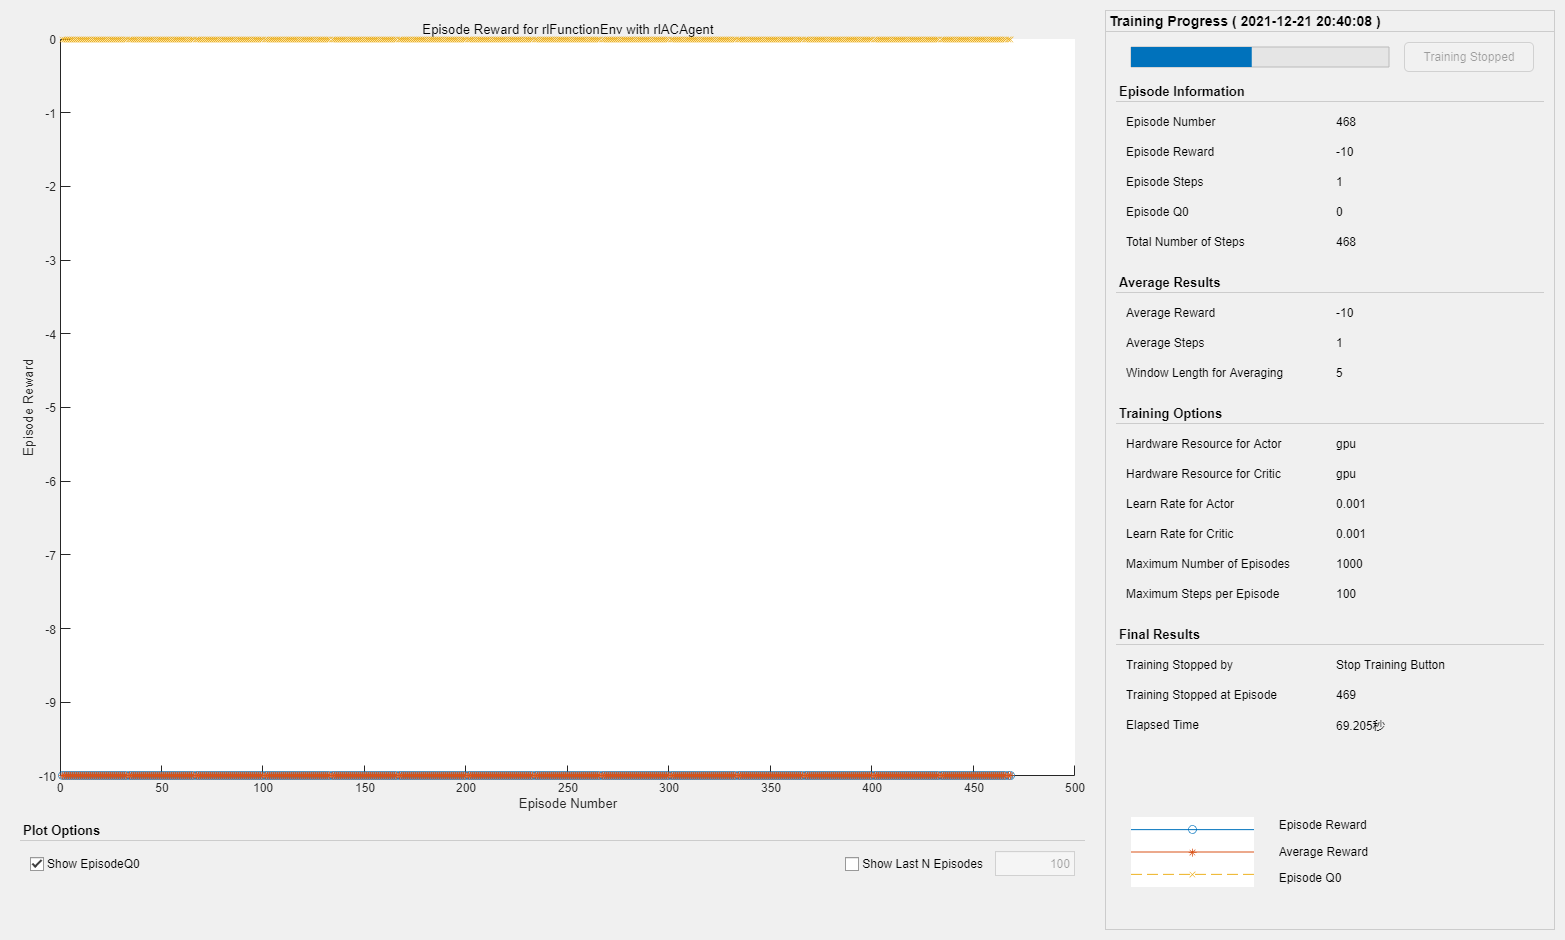

trainingStats = train(agent, rlEnv, trainOpts);